a) Compute gradient and Hessian

clear x y f1 f2 f3
syms x y 

f1(x,y) = 2.*x + 3.*y + 1;
f2(x,y) = x.^2 + y.^2 - x.*y - 5;
f3(x,y) = (x-5).*cos(y-5)-(y-5).*sin(x-5);

disp("For f1:");

For f1:


g1 = gradient(f1, [x,y])

$$g1(x, y) = \left(\begin{array}{c} 2\\ 3 \end{array}\right)$$

h1 = hessian(f1, [x,y])

$$h1(x, y) = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$


disp("For f2:");

For f2:


g2 = gradient(f2, [x,y])

$$g2(x, y) = \left(\begin{array}{c} 2\,x-y\\ 2\,y-x \end{array}\right)$$

h2 = hessian(f2, [x,y])

$$h2(x, y) = \left(\begin{array}{cc} 2 & -1\\ -1 & 2 \end{array}\right)$$


disp("For f3:");

For f3:


g3 = gradient(f3, [x,y])

$$g3(x, y) = \left(\begin{array}{c} \cos\left(y-5\right)-\cos\left(x-5\right)\,\left(y-5\right)\\ -\sin\left(x-5\right)-\sin\left(y-5\right)\,\left(x-5\right) \end{array}\right)$$

h3 = hessian(f3, [x,y])

$$h3(x, y) = \left(\begin{array}{cc} \sin\left(x-5\right)\,\left(y-5\right) & -\cos\left(x-5\right)-\sin\left(y-5\right)\\ -\cos\left(x-5\right)-\sin\left(y-5\right) & -\cos\left(y-5\right)\,\left(x-5\right) \end{array}\right)$$

b) Produce 2-D contour plot and 3-D quadratic approximation.

For f1:

Contour:

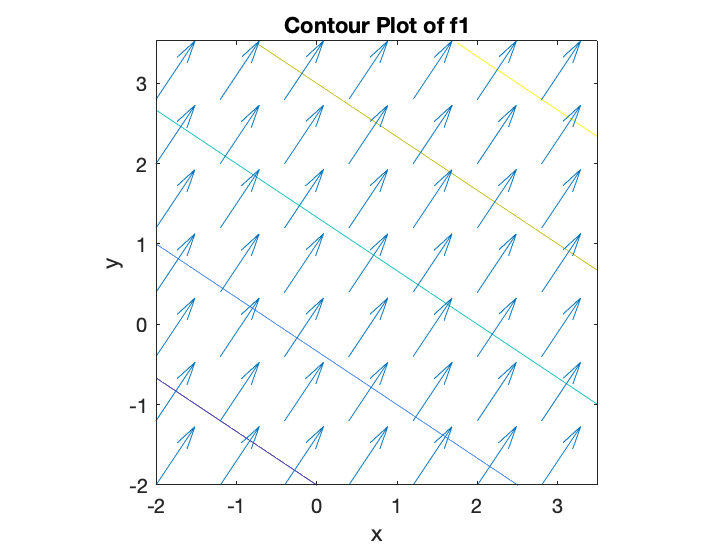

clear x y f1
syms x y f1
f1(x,y) = 2.*x + 3.*y + 1;
x = linspace(-2, 3.5);
y = linspace(-2, 3.5);
[X,Y] = meshgrid(x,y);
Z = f1(X,Y);
contour(X,Y,Z)
hold on 

spacing = 0.8;

x = -2:spacing:3.5;
y = -2:spacing:3.5;
[X,Y] = meshgrid(x,y);
Z = 2*X + 3*Y + 1;
[DX,DY] = gradient(Z, spacing);
quiver(X,Y,DX,DY)
axis equal
hold off

xlabel('x');
ylabel('y');
title('Contour Plot of f1');

3-D Quadratic Approximation

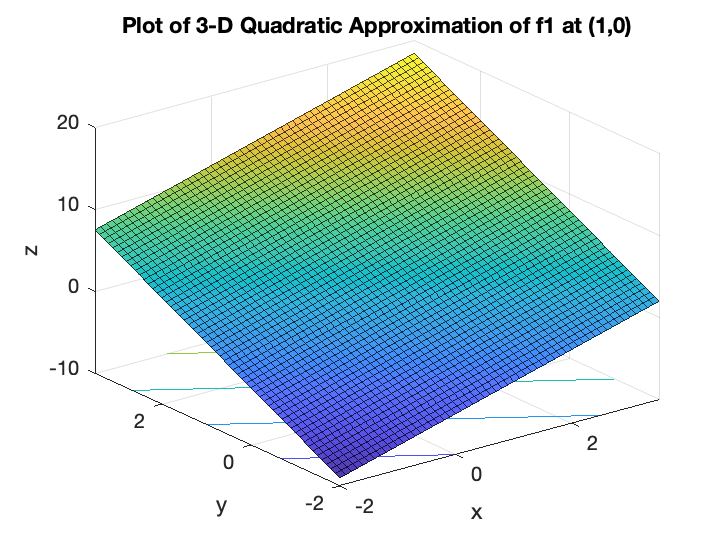

clear x y f1

f1 = @(x,y) 2.*x + 3.*y + 1;

spacing = 0.1;
[X,Y] = meshgrid(-2:spacing:3.5);
[dx,dy] = gradient(f1(X,Y),spacing);

x0 = 1;
y0 = 0;

t = (X == x0) & (Y == y0);
indt = find(t);
fx0 = dx(indt);
fy0 = dy(indt);

clear x y f1
syms x y f1
f1(x,y) = 2.*x + 3.*y + 1;
sol = hessian(f1);
sol = sol(X,Y);
sol = cell2sym(sol);
f2x1 = double(sol(1:56, 1:56));
f2x1 = f2x1(indt);
f2x2 = double(sol(1:56, 57:112));
f2x2 = f2x2(indt);
f2x3 = double(sol(1:56, 57:112));
f2x3 = f2x3(indt);
f2x4 = double(sol(57:112, 57:112));
f2x4 = f2x4(indt);

%compute tangent plane
f_approx = @(x,y) f1(x0,y0) + fx0*(x-x0) + fy0*(y-y0) + 1/2.*((x-x0).*((x-x0).*f2x1 + (y-y0).*f2x2)+(y-y0).*((x-x0).*f2x3+(y-y0).*f2x4));
surf(X,Y,double(f_approx(X,Y)),'EdgeAlpha',0.7,'FaceAlpha',0.9);
hold on
meshc(X,Y,f1(X,Y));
hold off
xlabel('x');
ylabel('y');
zlabel('z');
xlim([-2 3.5]);
ylim([-2 3.5]);
zlim([-10 20]);
title('Plot of 3-D Quadratic Approximation of f1 at (1,0)');

For f2

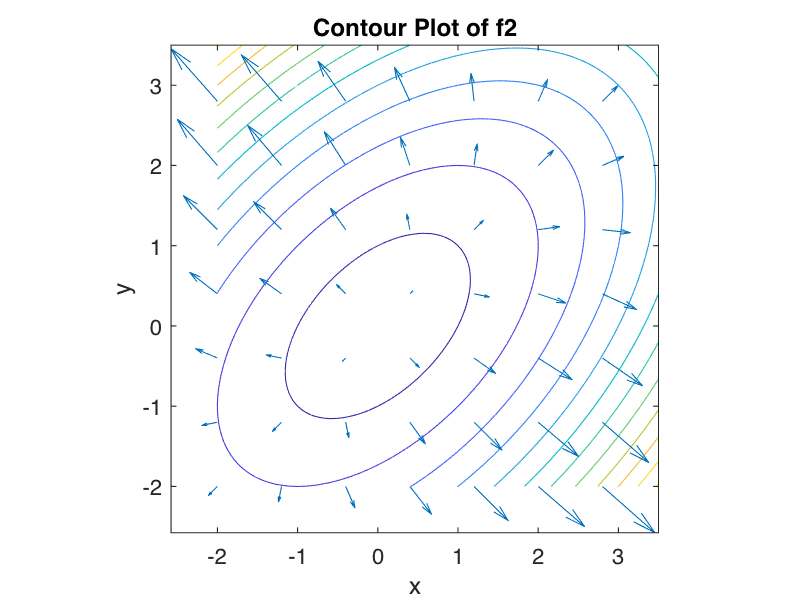

clear x y f2
syms x y f2
f2(x,y) = x.^2 + y.^2 - x.*y - 5;

x = linspace(-2, 3.5);
y = linspace(-2, 3.5);
[X,Y] = meshgrid(x,y);
Z = f2(X,Y);
contour(X,Y,Z)
hold on 

spacing = 0.8;

x = -2:spacing:3.5;
y = -2:spacing:3.5;
[X,Y] = meshgrid(x,y);
Z = X.^2 + Y.^2 - X.*Y - 5;
[DX,DY] = gradient(Z, spacing);
quiver(X,Y,DX,DY)
axis equal
hold off

xlabel('x');
ylabel('y');
title('Contour Plot of f2');

3-D Quadratic Apporximation

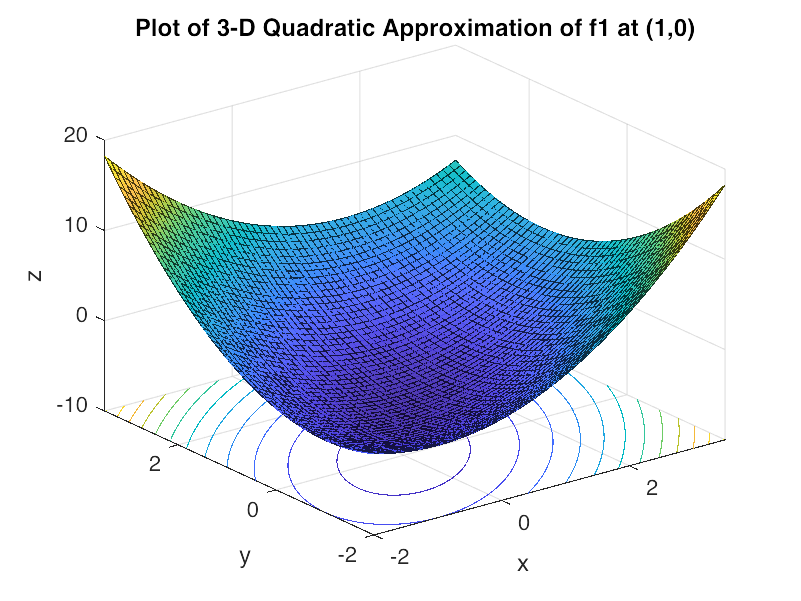

clear x y f2
f2 = @(x,y) x.^2 + y.^2 - x.*y - 5;

spacing = 0.1;
[X,Y] = meshgrid(-2:spacing:3.5);
[dx,dy] = gradient(f2(X,Y),spacing);

x0 = 1;
y0 = 0;

t = (X == x0) & (Y == y0);
indt = find(t);
fx0 = dx(indt);
fy0 = dy(indt);

clear x y f2
syms x y f2
f2(x,y) = x.^2 + y.^2 - x.*y - 5;
sol = hessian(f2);
sol = sol(X,Y);
sol = cell2sym(sol);
f2x1 = double(sol(1:56, 1:56));
f2x1 = f2x1(indt);
f2x2 = double(sol(1:56, 57:112));
f2x2 = f2x2(indt);
f2x3 = double(sol(1:56, 57:112));
f2x3 = f2x3(indt);
f2x4 = double(sol(57:112, 57:112));
f2x4 = f2x4(indt);

%compute tangent plane
f_approx = @(x,y) f2(x0,y0) + fx0*(x-x0) + fy0*(y-y0) + 1/2.*((x-x0).*((x-x0).*f2x1 + (y-y0).*f2x2)+(y-y0).*((x-x0).*f2x3+(y-y0).*f2x4));
surf(X,Y,double(f_approx(X,Y)),'EdgeAlpha',0.7,'FaceAlpha',0.9);
hold on
meshc(X,Y,f2(X,Y));
hold off
xlabel('x');
ylabel('y');
zlabel('z');
xlim([-2 3.5]);
ylim([-2 3.5]);
zlim([-10 20]);
title('Plot of 3-D Quadratic Approximation of f1 at (1,0)');

For f3

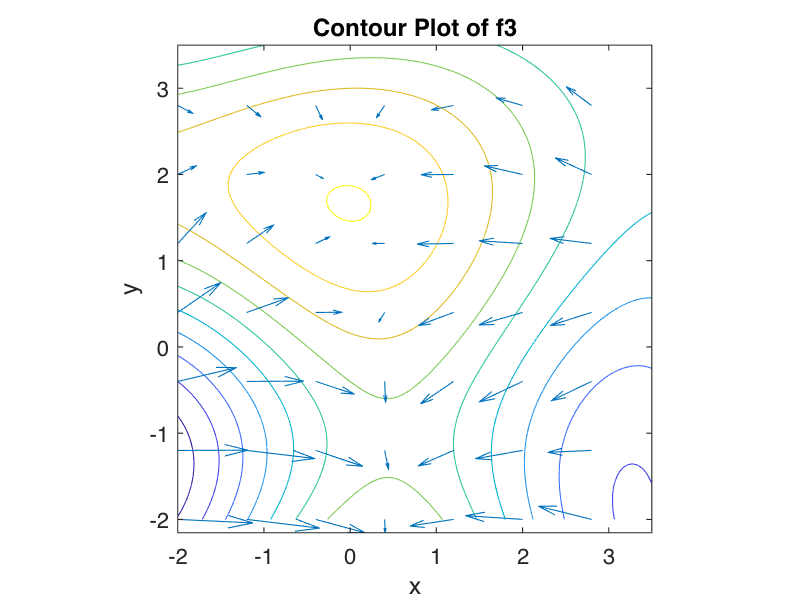

clear x y f3
syms x y f3
f3(x,y) = (x-5).*cos(y-5)-(y-5).*sin(x-5);

x = linspace(-2, 3.5);
y = linspace(-2, 3.5);
[X,Y] = meshgrid(x,y);
Z = f3(X,Y);
contour(X,Y,Z)
hold on 

spacing = 0.8;

x = -2:spacing:3.5;
y = -2:spacing:3.5;
[X,Y] = meshgrid(x,y);
Z = (X-Y).*cos(Y-5)-(Y-5).*sin(X-5);
[DX,DY] = gradient(Z, spacing);
quiver(X,Y,DX,DY)
axis equal
hold off

xlabel('x');
ylabel('y');
title('Contour Plot of f3');

3-D Quadratic Approximation

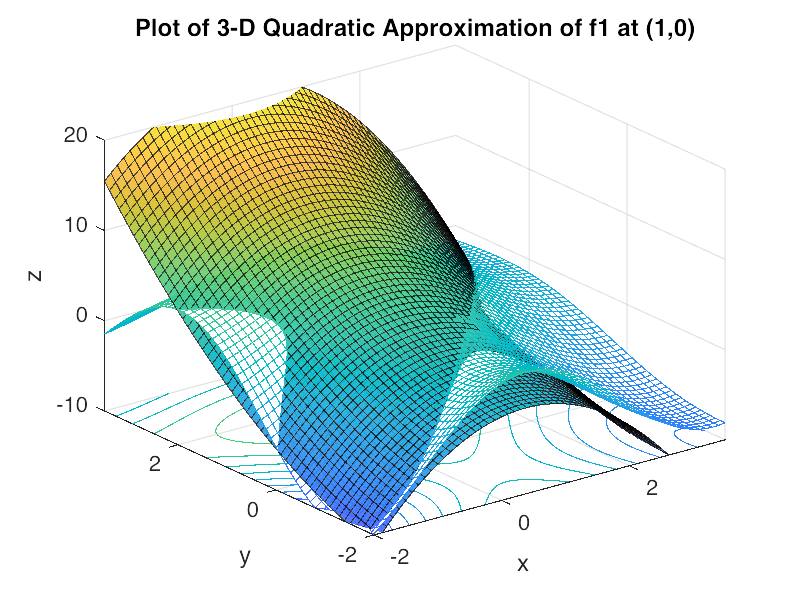

clear x y f3

f3 = @(x,y) (x-5).*cos(y-5)-(y-5).*sin(x-5);

spacing = 0.1;
[X,Y] = meshgrid(-2:spacing:3.5);
[dx,dy] = gradient(f3(X,Y),spacing);

x0 = 1;
y0 = 0;

t = (X == x0) & (Y == y0);
indt = find(t);
fx0 = dx(indt);
fy0 = dy(indt);

clear x y f3
syms x y f3
f3(x,y) = (x-5).*cos(y-5)-(y-5).*sin(x-5);
sol = hessian(f3);
sol = sol(X,Y);
sol = cell2sym(sol);
f2x1 = double(sol(1:56, 1:56));
f2x1 = f2x1(indt);
f2x2 = double(sol(1:56, 57:112));
f2x2 = f2x2(indt);
f2x3 = double(sol(1:56, 57:112));
f2x3 = f2x3(indt);
f2x4 = double(sol(57:112, 57:112));
f2x4 = f2x4(indt);

%compute tangent plane
f_approx = @(x,y) f3(x0,y0) + fx0*(x-x0) + fy0*(y-y0) + 1/2.*((x-x0).*((x-x0).*f2x1 + (y-y0).*f2x2)+(y-y0).*((x-x0).*f2x3+(y-y0).*f2x4));
surf(X,Y,double(f_approx(X,Y)),'EdgeAlpha',0.7,'FaceAlpha',0.9);
hold on
meshc(X,Y,f3(X,Y));
hold off
xlabel('x');
ylabel('y');
zlabel('z');
xlim([-2 3.5]);
ylim([-2 3.5]);
zlim([-10 20]);
title('Plot of 3-D Quadratic Approximation of f1 at (1,0)');

c) Repeat for (x,y) = (-0.7, 2)

For f1:

Contour:

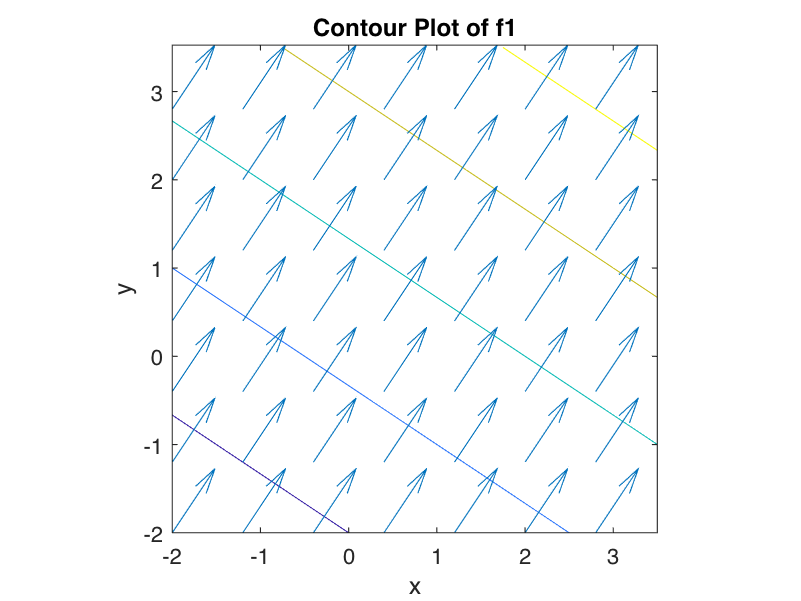

clear x y f1
syms x y f1
f1(x,y) = 2.*x + 3.*y + 1;

x = linspace(-2, 3.5);
y = linspace(-2, 3.5);
[X,Y] = meshgrid(x,y);
Z = f1(X,Y);
contour(X,Y,Z)
hold on 

spacing = 0.8;

x = -2:spacing:3.5;
y = -2:spacing:3.5;
[X,Y] = meshgrid(x,y);
Z = 2*X + 3*Y + 1;
[DX,DY] = gradient(Z, spacing);
quiver(X,Y,DX,DY)
axis equal
hold off

xlabel('x');
ylabel('y');
title('Contour Plot of f1');

3-D Quadratic Approximation

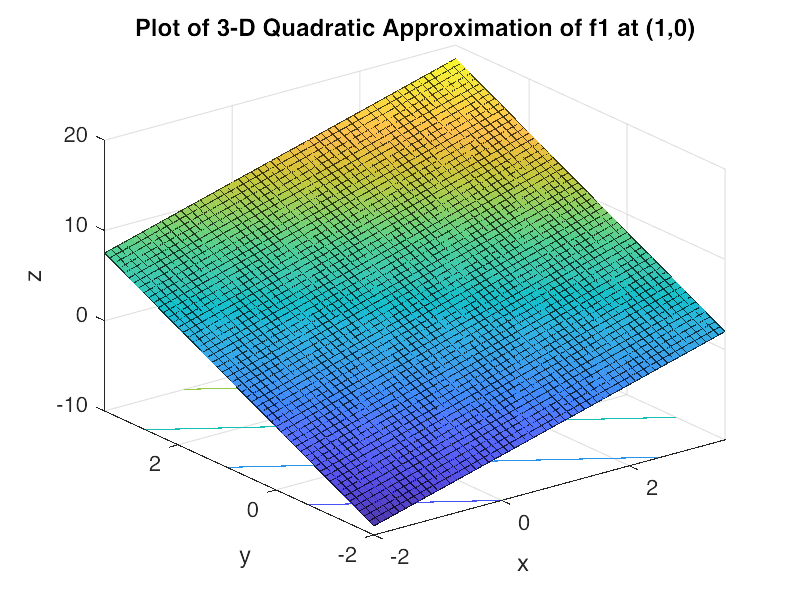

clear x y f1

f1 = @(x,y) 2.*x + 3.*y + 1;

spacing = 0.1;
[X,Y] = meshgrid(-2:spacing:3.5);
[dx,dy] = gradient(f1(X,Y),spacing);

x0 = -0.7;
y0 = 2;

t = (X == x0) & (Y == y0);
indt = find(t);
fx0 = dx(indt);
fy0 = dy(indt);

clear x y f1
syms x y f1
f1(x,y) = 2.*x + 3.*y + 1;
sol = hessian(f1);
sol = sol(X,Y);
sol = cell2sym(sol);
f2x1 = double(sol(1:56, 1:56));
f2x1 = f2x1(indt);
f2x2 = double(sol(1:56, 57:112));
f2x2 = f2x2(indt);
f2x3 = double(sol(1:56, 57:112));
f2x3 = f2x3(indt);
f2x4 = double(sol(57:112, 57:112));
f2x4 = f2x4(indt);

%compute tangent plane
f_approx = @(x,y) f1(x0,y0) + fx0.*(x-x0) + fy0.*(y-y0) + 1/2.*((x-x0).*((x-x0).*f2x1 + (y-y0).*f2x2)+(y-y0).*((x-x0).*f2x3+(y-y0).*f2x4));
surf(X,Y,double(f_approx(X,Y)),'EdgeAlpha',0.7,'FaceAlpha',0.9);
hold on
meshc(X,Y,f1(X,Y));
hold off
xlabel('x');
ylabel('y');
zlabel('z');
xlim([-2 3.5]);
ylim([-2 3.5]);
zlim([-10 20]);
title('Plot of 3-D Quadratic Approximation of f1 at (1,0)');

For f2

clear x y f2
syms x y f2
f2(x,y) = x.^2 + y.^2 - x.*y - 5;

x = linspace(-2, 3.5);
y = linspace(-2, 3.5);
[X,Y] = meshgrid(x,y);
Z = f2(X,Y);
contour(X,Y,Z)
hold on 

spacing = 0.8;

x = -2:spacing:3.5;
y = -2:spacing:3.5;
[X,Y] = meshgrid(x,y);
Z = X.^2 + Y.^2 - X.*Y - 5;
[DX,DY] = gradient(Z, spacing);
quiver(X,Y,DX,DY)
axis equal
hold off

xlabel('x');
ylabel('y');
title('Contour Plot of f2');

3-D Quadratic Apporximation

clear x y f2

f2 = @(x,y) x.^2 + y.^2 - x.*y - 5;

spacing = 0.1;
[X,Y] = meshgrid(-2:spacing:3.5);
[dx,dy] = gradient(f2(X,Y),spacing);

x0 = -0.7;
y0 = 2;

t = (X == x0) & (Y == y0);
indt = find(t);
fx0 = dx(indt);
fy0 = dy(indt);

clear x y f2
syms x y f2
f2(x,y) = x.^2 + y.^2 - x.*y - 5;
sol = hessian(f2);
sol = sol(X,Y);
sol = cell2sym(sol);
f2x1 = double(sol(1:56, 1:56));
f2x1 = f2x1(indt);
f2x2 = double(sol(1:56, 57:112));
f2x2 = f2x2(indt);
f2x3 = double(sol(1:56, 57:112));
f2x3 = f2x3(indt);
f2x4 = double(sol(57:112, 57:112));
f2x4 = f2x4(indt);

%compute tangent plane
f_approx = @(x,y) f2(x0,y0) + fx0*(x-x0) + fy0*(y-y0) + 1/2.*((x-x0).*((x-x0).*f2x1 + (y-y0).*f2x2)+(y-y0).*((x-x0).*f2x3+(y-y0).*f2x4));
surf(X,Y,double(f_approx(X,Y)),'EdgeAlpha',0.7,'FaceAlpha',0.9);
hold on
meshc(X,Y,f2(X,Y));
hold off
xlabel('x');
ylabel('y');
zlabel('z');
xlim([-2 3.5]);
ylim([-2 3.5]);
zlim([-10 20]);
title('Plot of 3-D Quadratic Approximation of f1 at (1,0)');

For f3

clear x y f3
syms x y f3
f3(x,y) = (x-5).*cos(y-5)-(y-5).*sin(x-5);

x = linspace(-2, 3.5);
y = linspace(-2, 3.5);
[X,Y] = meshgrid(x,y);
Z = f3(X,Y);
contour(X,Y,Z)
hold on 

spacing = 0.8;

x = -2:spacing:3.5;
y = -2:spacing:3.5;
[X,Y] = meshgrid(x,y);
Z = (X-Y).*cos(Y-5)-(Y-5).*sin(X-5);
[DX,DY] = gradient(Z, spacing);
quiver(X,Y,DX,DY)
axis equal
hold off

xlabel('x');
ylabel('y');
title('Contour Plot of f3');

3-D Quadratic Approximation

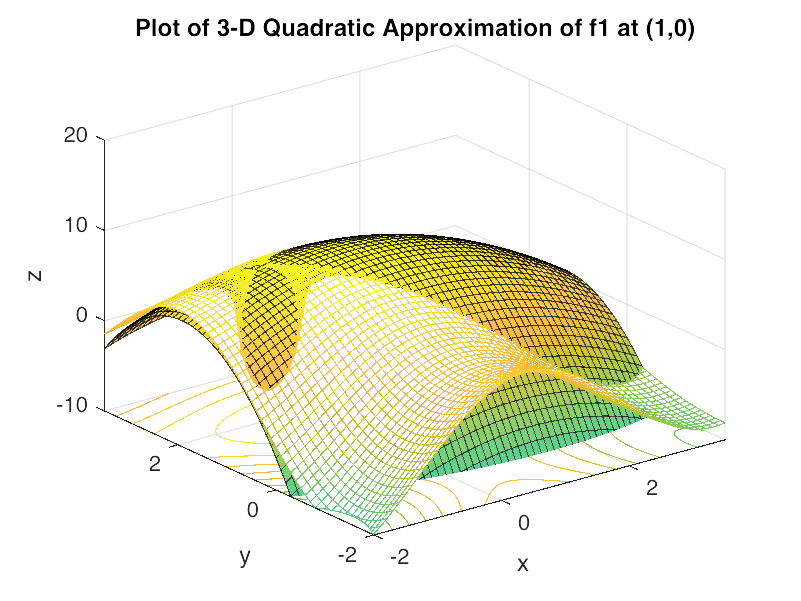

clear x y f3

f3 = @(x,y) (x-5).*cos(y-5)-(y-5).*sin(x-5);

spacing = 0.1;
[X,Y] = meshgrid(-2:spacing:3.5);
[dx,dy] = gradient(f3(X,Y),spacing);

x0 = -0.7;
y0 = 2;

t = (X == x0) & (Y == y0);
indt = find(t);
fx0 = dx(indt);
fy0 = dy(indt);

clear x y f3
syms x y f3
f3(x,y) = (x-5).*cos(y-5)-(y-5).*sin(x-5);
sol = hessian(f3);
sol = sol(X,Y);
sol = cell2sym(sol);
f2x1 = double(sol(1:56, 1:56));
f2x1 = f2x1(indt);
f2x2 = double(sol(1:56, 57:112));
f2x2 = f2x2(indt);
f2x3 = double(sol(1:56, 57:112));
f2x3 = f2x3(indt);
f2x4 = double(sol(57:112, 57:112));
f2x4 = f2x4(indt);

%compute tangent plane
f_approx = @(x,y) f3(x0,y0) + fx0*(x-x0) + fy0*(y-y0) + 1/2.*((x-x0).*((x-x0).*f2x1 + (y-y0).*f2x2)+(y-y0).*((x-x0).*f2x3+(y-y0).*f2x4));
surf(X,Y,double(f_approx(X,Y)),'EdgeAlpha',0.7,'FaceAlpha',0.9);
hold on
meshc(X,Y,f3(X,Y));
hold off
xlabel('x');
ylabel('y');
zlabel('z');
xlim([-2 3.5]);
ylim([-2 3.5]);
zlim([-10 20]);
title('Plot of 3-D Quadratic Approximation of f1 at (1,0)');

Repeat for (x,y) = (2.5,-1)

For f1:

Contour:

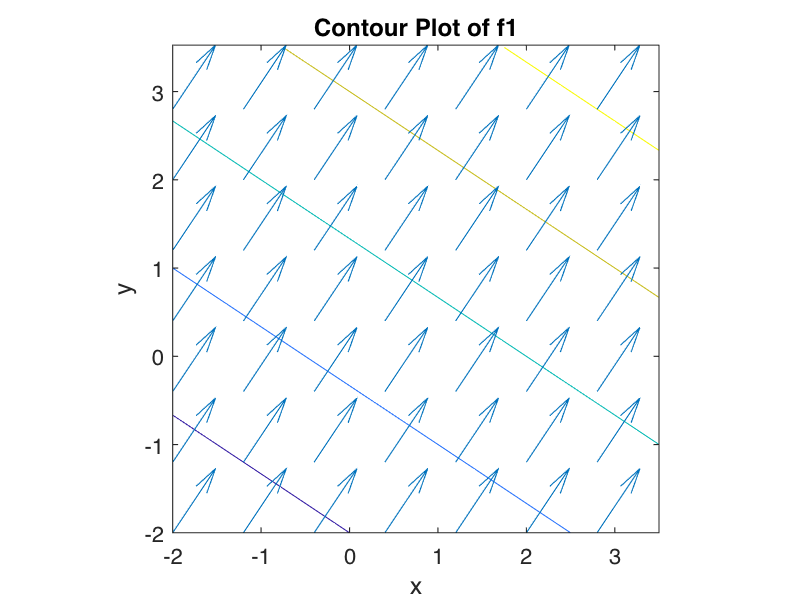

clear x y f1
syms x y f1
f1(x,y) = 2.*x + 3.*y + 1;

x = linspace(-2, 3.5);
y = linspace(-2, 3.5);
[X,Y] = meshgrid(x,y);
Z = f1(X,Y);
contour(X,Y,Z)
hold on 

spacing = 0.8;

x = -2:spacing:3.5;
y = -2:spacing:3.5;
[X,Y] = meshgrid(x,y);
Z = 2*X + 3*Y + 1;
[DX,DY] = gradient(Z, spacing);
quiver(X,Y,DX,DY)
axis equal
hold off

xlabel('x');
ylabel('y');
title('Contour Plot of f1');

3-D Quadratic Approximation

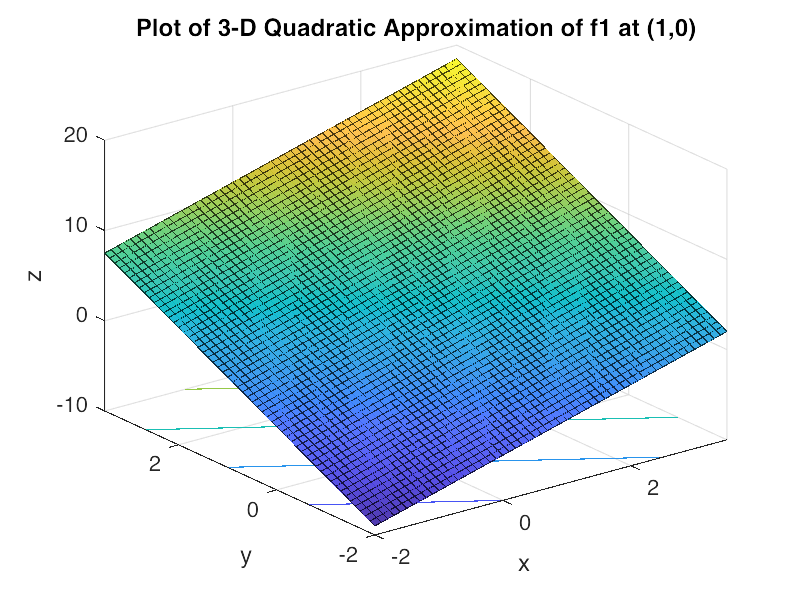

clear x y f1

f1 = @(x,y) 2.*x + 3.*y + 1;

spacing = 0.1;
[X,Y] = meshgrid(-2:spacing:3.5);
[dx,dy] = gradient(f1(X,Y),spacing);

x0 = 2.5;
y0 = -1;

t = (X == x0) & (Y == y0);
indt = find(t);
fx0 = dx(indt);
fy0 = dy(indt);

clear x y f1
syms x y f1
f1(x,y) = 2.*x + 3.*y + 1;
sol = hessian(f1);
sol = sol(X,Y);
sol = cell2sym(sol);
f2x1 = double(sol(1:56, 1:56));
f2x1 = f2x1(indt);
f2x2 = double(sol(1:56, 57:112));
f2x2 = f2x2(indt);
f2x3 = double(sol(1:56, 57:112));
f2x3 = f2x3(indt);
f2x4 = double(sol(57:112, 57:112));
f2x4 = f2x4(indt);

%compute tangent plane
f_approx = @(x,y) f1(x0,y0) + fx0.*(x-x0) + fy0.*(y-y0) + 1/2.*((x-x0).*((x-x0).*f2x1 + (y-y0).*f2x2)+(y-y0).*((x-x0).*f2x3+(y-y0).*f2x4));
surf(X,Y,double(f_approx(X,Y)),'EdgeAlpha',0.7,'FaceAlpha',0.9);
hold on
meshc(X,Y,f1(X,Y));
hold off
xlabel('x');
ylabel('y');
zlabel('z');
xlim([-2 3.5]);
ylim([-2 3.5]);
zlim([-10 20]);
title('Plot of 3-D Quadratic Approximation of f1 at (1,0)');

For f2

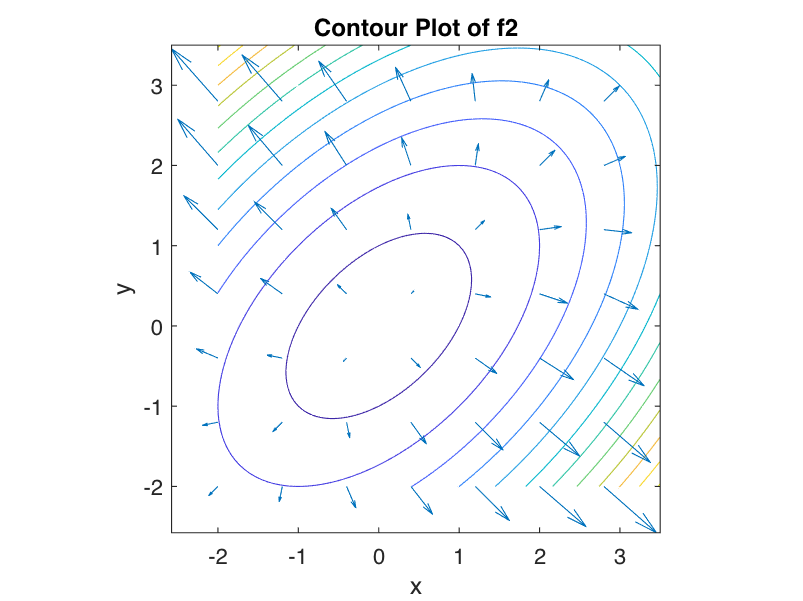

clear x y f2
syms x y f2
f2(x,y) = x.^2 + y.^2 - x.*y - 5;

x = linspace(-2, 3.5);
y = linspace(-2, 3.5);
[X,Y] = meshgrid(x,y);
Z = f2(X,Y);
contour(X,Y,Z)
hold on 

spacing = 0.8;

x = -2:spacing:3.5;
y = -2:spacing:3.5;
[X,Y] = meshgrid(x,y);
Z = X.^2 + Y.^2 - X.*Y - 5;
[DX,DY] = gradient(Z, spacing);
quiver(X,Y,DX,DY)
axis equal
hold off

xlabel('x');
ylabel('y');
title('Contour Plot of f2');

3-D Quadratic Apporximation

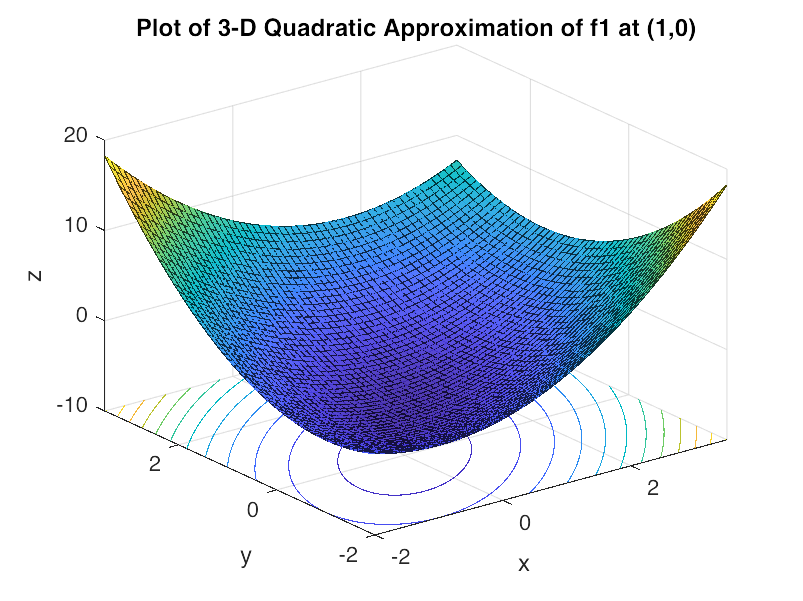

clear x y f2

f2 = @(x,y) x.^2 + y.^2 - x.*y - 5;

spacing = 0.1;
[X,Y] = meshgrid(-2:spacing:3.5);
[dx,dy] = gradient(f2(X,Y),spacing);

x0 = 2.5;
y0 = -1;

t = (X == x0) & (Y == y0);
indt = find(t);
fx0 = dx(indt);
fy0 = dy(indt);

clear x y f2
syms x y f2
f2(x,y) = x.^2 + y.^2 - x.*y - 5;
sol = hessian(f2);
sol = sol(X,Y);
sol = cell2sym(sol);
f2x1 = double(sol(1:56, 1:56));
f2x1 = f2x1(indt);
f2x2 = double(sol(1:56, 57:112));
f2x2 = f2x2(indt);
f2x3 = double(sol(1:56, 57:112));
f2x3 = f2x3(indt);
f2x4 = double(sol(57:112, 57:112));
f2x4 = f2x4(indt);

%compute tangent plane
f_approx = @(x,y) f2(x0,y0) + fx0*(x-x0) + fy0*(y-y0) + 1/2.*((x-x0).*((x-x0).*f2x1 + (y-y0).*f2x2)+(y-y0).*((x-x0).*f2x3+(y-y0).*f2x4));
surf(X,Y,double(f_approx(X,Y)),'EdgeAlpha',0.7,'FaceAlpha',0.9);
hold on
meshc(X,Y,f2(X,Y));
hold off
xlabel('x');
ylabel('y');
zlabel('z');
xlim([-2 3.5]);
ylim([-2 3.5]);
zlim([-10 20]);
title('Plot of 3-D Quadratic Approximation of f1 at (1,0)');

For f3

clear x y f3
syms x y f3
f3(x,y) = (x-5).*cos(y-5)-(y-5).*sin(x-5);

x = linspace(-2, 3.5);
y = linspace(-2, 3.5);
[X,Y] = meshgrid(x,y);
Z = f3(X,Y);
contour(X,Y,Z)
hold on 

spacing = 0.8;

x = -2:spacing:3.5;
y = -2:spacing:3.5;
[X,Y] = meshgrid(x,y);
Z = (X-Y).*cos(Y-5)-(Y-5).*sin(X-5);
[DX,DY] = gradient(Z, spacing);
quiver(X,Y,DX,DY)
axis equal
hold off

xlabel('x');
ylabel('y');
title('Contour Plot of f3');

3-D Quadratic Approximation

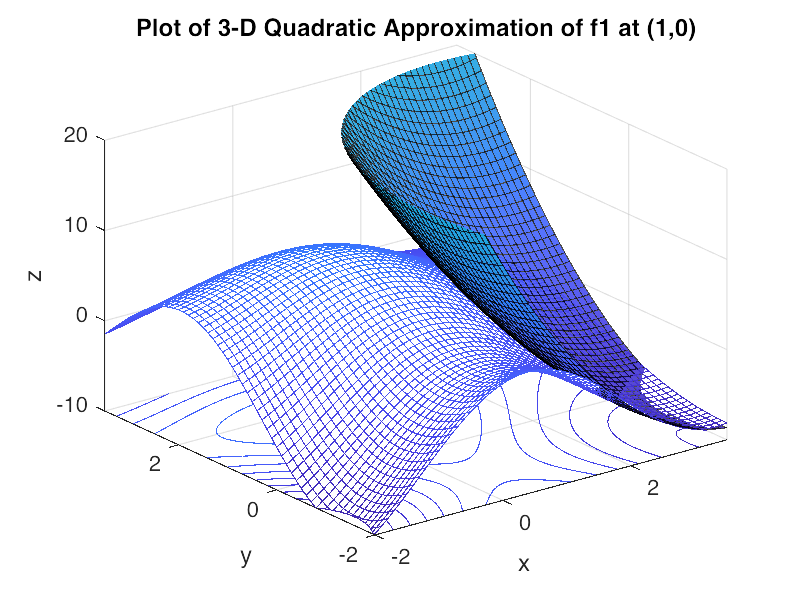

clear x y f3

f3 = @(x,y) (x-5).*cos(y-5)-(y-5).*sin(x-5);

spacing = 0.1;
[X,Y] = meshgrid(-2:spacing:3.5);
[dx,dy] = gradient(f3(X,Y),spacing);

x0 = 2.5;
y0 = -1;

t = (X == x0) & (Y == y0);
indt = find(t);
fx0 = dx(indt);
fy0 = dy(indt);

clear x y f3
syms x y f3
f3(x,y) = (x-5).*cos(y-5)-(y-5).*sin(x-5);
sol = hessian(f3);
sol = sol(X,Y);
sol = cell2sym(sol);
f2x1 = double(sol(1:56, 1:56));
f2x1 = f2x1(indt);
f2x2 = double(sol(1:56, 57:112));
f2x2 = f2x2(indt);
f2x3 = double(sol(1:56, 57:112));
f2x3 = f2x3(indt);
f2x4 = double(sol(57:112, 57:112));
f2x4 = f2x4(indt);

%compute tangent plane
f_approx = @(x,y) f3(x0,y0) + fx0*(x-x0) + fy0*(y-y0) + 1/2.*((x-x0).*((x-x0).*f2x1 + (y-y0).*f2x2)+(y-y0).*((x-x0).*f2x3+(y-y0).*f2x4));
surf(X,Y,double(f_approx(X,Y)),'EdgeAlpha',0.7,'FaceAlpha',0.9);
hold on
meshc(X,Y,f3(X,Y));
hold off
xlabel('x');
ylabel('y');
zlabel('z');
xlim([-2 3.5]);
ylim([-2 3.5]);
zlim([-10 20]);
title('Plot of 3-D Quadratic Approximation of f1 at (1,0)');

d) Comment on where your functions are accurate and when they are not. Discuss what the reason is behind your observations.

Using quadratic approximation, f1 and f2 are modeled perfectly for all points. For f3, the function approximation is accurate near the specified point. However, the quadratic function is unable to model non-quadratic regions as f3 is composed of sinusoidal terms.